clear
close all
clc

**Porteføljeopgave i AFS:**

**Cauerfilter**

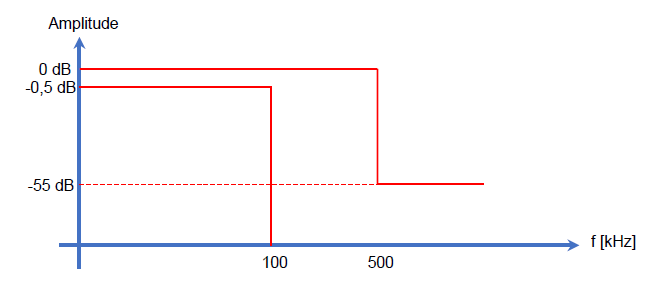

**1. Bestem den mindste filterorden, som overholder de stillede krav.**

Dette gøres med funktionen "ellipord".

wp = 100000*2*pi; % Pasbåndfrekvens
ws = 500000*2*pi; % Stopbåndfrekvens
Ap = 0.5; % Pasbåndripple
As = 55; % Stopbånddæmpning

[N,wp] = ellipord(wp,ws,Ap,As,'s')

N = 3

wp = 6.2832e+05

Funktionen viser, at et filter med orden N = 3 er påkrævet for at overholde kravene.

**2. Vis amplitude- og fasekarakteristik.**

Karakteristikkerne vises ved først at finde den denormerede overføringsfunktion.

[zn,pn,kn] = ellipap(N,Ap,As); % Normerede poler og nulpunkter
[numn,denn] = zp2tf(zn,pn,kn); % Normeret tæller og nævner
Hsn = tf(numn,denn) % Normeret overføringsfunktion


Hsn =
 
         0.02481 s^2 + 0.7282
  ----------------------------------
  s^3 + 1.248 s^2 + 1.533 s + 0.7282
 
Continuous-time transfer function.



For at denormere anvendes denormeringsfaktoren Ω, der er lig pasbåndfrekvensen.

Omega_n = wp;
s = tf('s');
s_n = s/Omega_n;

% Denormerede overføringsfunktion:
Hs = (0.02481*(s_n)^2+0.7282)/((s_n)^3+1.248*(s_n)^2+1.533*s_n+0.7282)


Hs =
 
                1.527e33 s^2 + 1.769e46
  ---------------------------------------------------
  9.793e28 s^3 + 7.679e34 s^2 + 5.927e40 s + 1.769e46
 
Continuous-time transfer function.



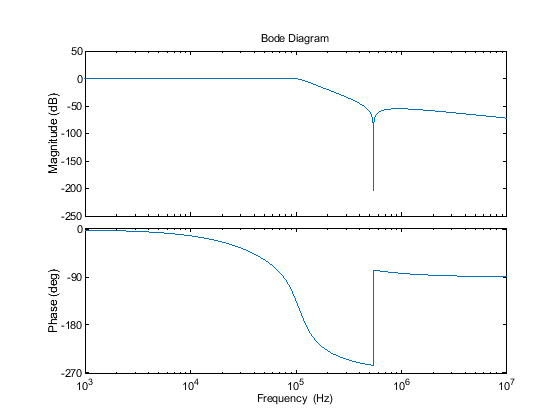

[num,den] = tfdata(Hs);

opts = bodeoptions;
opts.FreqUnits = 'Hz';

bode(Hs,opts) % Plot af amplitude- og fasekarakteristik

**3. Realiser som passivt "ladder-kredsløb", når Rg = Rb = 1 kΩ.**

Overføringsfunktionen realiseres med funktionen CA_LADDER. Ordenen er ulige, og der skal derfor ikke tages højde for diverse cases.

Rg = 1000;
Rb = 1000;

[G,Z,R,P] = CA_POLES(wp,ws,Ap,As,N);

[L,C] = CA_LADDER(G,Z,R,P,wp,ws,Rg,Rb,0)

L =          0    0.0017         0


C = 	1.0e+-8 *

    0.2500    0.0051    0.2500


% Ladder = 0 for at reducere antal spoler.

Tallene indikerer, at den første kondensator er 2.5 nF og til stel. Fra denne er en spole på 1.7 mH parallelt med en kondensator på 51 pF mod udgangen af filteret. Til sidst er en kondensator på 2.5 nF til stel.

**4. Filteret skal realiseres som et aktivt filter, ved en kaskadekobling af 1. og 2. ordens filtre. Bestem ω0 og Q for poler og nulpunkter, for ét af disse 2. ordens filtre.**

2. ordens filtret findes ved at opdele overføringsfunktionen med funktionen tf2sos.

[sos,g] = zp2sos(Z,P,G)

sos = 	1.0e+13 *

         0    0.0000         0    0.0000    0.0000         0
    0.0000         0    1.1585    0.0000    0.0000    0.0452


g = 1.5590e+04


num1 = [sos(1,1) sos(1,3) sos(1,2)];
den1 = [sos(1,6) sos(1,4) sos(1,5)];
num2 = [sos(2,1) sos(2,2) sos(2,3)];
den2 = [sos(2,4) sos(2,5) sos(2,6)];
Hs1 = tf(num1,den1)*g


Hs1 =
 
  1.559e04
  --------
  s + 4e05
 
Continuous-time transfer function.



Hs2 = tf(num2,den2)


Hs2 =
 
        s^2 + 1.159e13
  ---------------------------
  s^2 + 3.844e05 s + 4.516e11
 
Continuous-time transfer function.




w0 = sqrt(4.515519254773533e+11)

w0 = 6.7198e+05

Q = w0/3.844052822091897e+05

Q = 1.7481